# SISTEMES d'EQUACIONS (SESSIÓ 8)

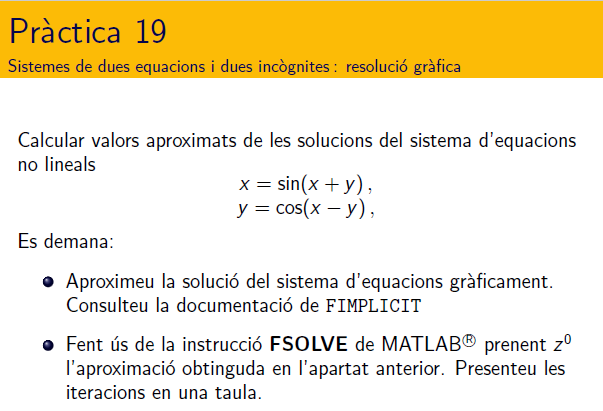

#### Resolució.

- Representeu en un mateix gràfic, les corbes $x-\sin(x+y)=0$ i $y-\cos(x-y)=0$ per a $x\in[-5,5]$ i per a $y\in[-5,5]$

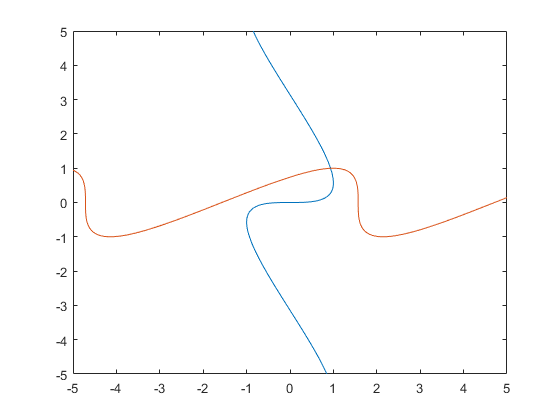

F1=@(x,y)x-sin(x+y);
F2=@(x,y)y-cos(x-y);
fimplicit({F1,F2})              

-  Canvieu el domini de les variables x i y a l'entorn del punt on es creuen les dues gràfiques

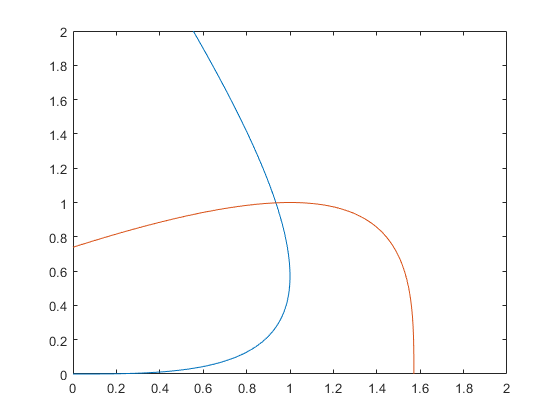

fimplicit({F1,F2},[ 0, 2 ,0 , 2])   

-  Calcular el punt on es creuen les dues gràfiques amb **FSOLVE** de Matlab. Per això cal definir el sistema d'equacions en una funció. (vegeu al final del document)

%doc fsolve
clearvars;
F = system([1,1]); disp(F')   % Valor de la funció que defineix el sistema d'equacions en [1;1]

    0.0907
         0



options = optimoptions('fsolve','Display','iter');
z0 = [1;1]; 
[x,fval] = fsolve(@system,z0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00822696                         0.128               1
     1          6     7.74869e-06      0.0640488        0.00285               1
     2          9      1.4696e-11     0.00216057       5.09e-06               1
     3         12     3.04197e-23    2.70288e-06       6.97e-12               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem a

x =     0.9351
    0.9980


fval = 	1.0e+-11 *

    0.5227    0.1759


# SISTEMES d'EQUACIONS (SESSIÓ 8)

## 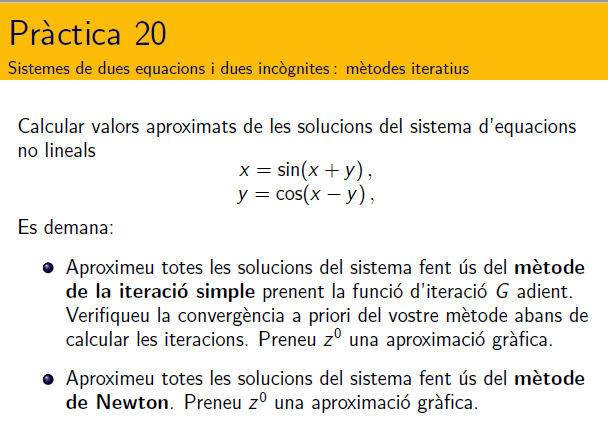

## Método del punto fijo

**Método del punto fijo con control del error y del número de iteraciones**

Matriz jacobiana de la función d'iteración calculada en Symbolic Math Toolbox

%%---SymbolicMathToolbox------------------------------------------------------------
syms x y
G(x,y)=[sin(x+y); cos(x-y)]                % Función de iteración

$$G(x, y) = \left(\begin{array}{c} \sin\left(x+y\right)\\ \cos\left(x-y\right) \end{array}\right)$$

JG(x,y)=jacobian(G(x,y),[x,y])             % Matriz jacobiana de la función de iteración

$$JG(x, y) = \left(\begin{array}{cc} \cos\left(x+y\right) & \cos\left(x+y\right)\\ -\sin\left(x-y\right) & \sin\left(x-y\right) \end{array}\right)$$

Z0=[1;0.9]

Z0 =     1.0000
    0.9000


control=JG(Z0(1),Z0(2)); 
control2=norm(control,1); 
criteriTEOREMA=vpa(control2,8)

$$criteriTEOREMA = 0.42312298$$

%%----Aritmética de punto flotante------------------------------------------------------
clear x y G(x,y) JG(x,y)
if criteriTEOREMA >=1 
    error('método divergente')
else
    disp('método convergente')
    G=@(x,y)[sin(x+y); cos(x-y)];
    F=@(x,y)[x-sin(x+y); y-cos(x-y)];
    %---- función itera2d
    alpha = metodo_punto_fijo(G,F,Z0,25,0.5*10^(-7));
end

método convergente



solución = 0.93508     0.99802
tolF = 5.1695e-09
tolZ = 2.5841e-08
iteraciones = 11



## Método de Newton

Criterio con control del error y del número de iteraciones

clearvars; format short g;

Z0=[1;0.9]  

Z0 =             1
          0.9


F=@(x,y)[x-sin(x+y); y-cos(x-y)]; F(Z0(1),Z0(2))

ans =        0.0537
    -0.095004


DF=@(x,y)[1-cos(x+y), -cos(x+y); sin(x-y), 1-sin(x-y)]; DF(Z0(1),Z0(2))

ans =        1.3233      0.32329
     0.099833      0.90017


tolZ=0.5*10^(-7);
tolF= 0.5*10^(-7); 
Nmax=10;
%----función newton2d
alpha = newton(F,DF,Z0,Nmax,tolF,tolZ); 


solución = 0.93508     0.99802
tolF = 2.2204e-16
tolZ = 1.2616e-08
iteraciones = 4



function F=system(z)
    F(1) = z(1)-sin(z(1)+z(2));
    F(2) = z(2)-cos(z(1)-z(2));
end

function alpha = metodo_punto_fijo(G,F,Z,Nmax,tol)
k=0; 
tolZ=norm(Z);
FZ=F(Z(1),Z(2)); 
tolF= norm(FZ); 

while (k<Nmax && (tolF>tol || tolZ>tol))
        Zold=Z;
        Z=G(Z(1),Z(2));
        tolF=norm(F(Z(1),Z(2)));
        tolZ=norm(Z-Zold);
        k=k+1;
end
alpha=Z;
fprintf('\n')
disp(['solución = ',num2str(Z')]);
disp(['tolF = ',num2str(tolF)]);
disp(['tolZ = ',num2str(tolZ)]);
disp(['iteraciones = ',num2str(k)]);
fprintf('\n')
end
function alpha = newton(F,DF,Z,Nmax,tolF,tolZ)
% Mètode de Newton per a funcions de dues variables
k=0; cotaF=1; cotaZ=1;
FZ=F(Z(1),Z(2)); 
DFZ=DF(Z(1),Z(2)); 
while (k<Nmax && (cotaF>tolF || cotaZ>tolZ))
    Zold=Z;
    Y=DFZ\(-FZ);
    Z=Zold+Y;
    cotaZ=norm(Y);
    DFZ=DF(Z(1),Z(2));
    FZ=F(Z(1),Z(2));
    cotaF=norm(FZ);
    k=k+1;
end
alpha=Z;
fprintf('\n')
disp(['solución = ',num2str(Z')]);
disp(['tolF = ',num2str(cotaF)]);
disp(['tolZ = ',num2str(cotaZ)]);
disp(['iteraciones = ',num2str(k)]);
fprintf('\n')
end

